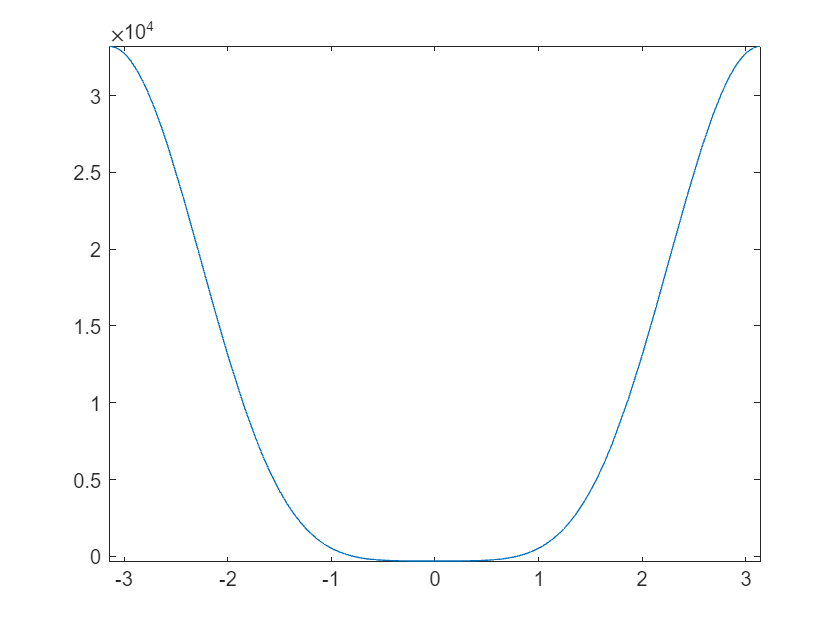

clc; clear; close all;
%%% Q2
% define constant variables for part a
L1 = 2; L2 = sqrt(2); L3 = sqrt(2);
gamma = pi/2;
p1 = sqrt(5); p2 = sqrt(5); p3 = sqrt(5);
x1 = 4; x2 = 0; y2 = 4;

% % define constant variables for part c
% L1 = 3; L2 = 3*sqrt(2); L3 = 3;
% gamma = pi/4;
% p1 = 5; p2 = 5; p3 = 3;
% x1 = 5; x2 = 0; y2 = 6;
% p2 = 7;

% define constant variables for part c

% define functional relationships
A2 = @(theta) L3 .* cos(theta) - x1;
B2 = @(theta) L3 .* sin(theta);
A3 = @(theta) L2 .* cos(theta + gamma) - x2;
B3 = @(theta) L2 .* sin(theta + gamma) - y2 ;

N1 = @(theta) B3(theta).*(p2^2-p1^2-A2(theta).^2-B2(theta).^2) ...
    - B2(theta).*(p3^2-p1^2-A3(theta).^2-B3(theta).^2);

N2 = @(theta) -A3(theta).*(p2^2-p1^2-A2(theta).^2-B2(theta).^2) ...
    + A2(theta).*(p3^2-p1^2-A3(theta).^2-B3(theta).^2);
D = @(theta) 2*(A2(theta).*B3(theta)-B2(theta).*A3(theta));

f = @(theta) N1(theta).^2 + N2(theta).^2 - p1^2 * D(theta).^2;

% plot and solve f(theta)
fplot(f, [-pi pi])

theta_roots = rad2deg(incremental_search(f, [-pi pi], 0.001))

theta_roots =   -45.0111   44.9432


% theta = inverse_quadratic_interpolation(f, pi, pi/2, pi/3, 1e-6, 1000)
% theta = inverse_quadratic_interpolation(f, -pi, -pi/2, -pi/3, 1e-6, 1000)
% theta = false_position(f, [0 pi], 1e-6, 1000)
% theta = bisection(f, [-pi pi], 1e-6, 1000)
theta_roots = modified_secant_method(f, -pi, 0.01, 1e-6, 1000)


root =

     []



theta_roots = -107.5995

i = 1

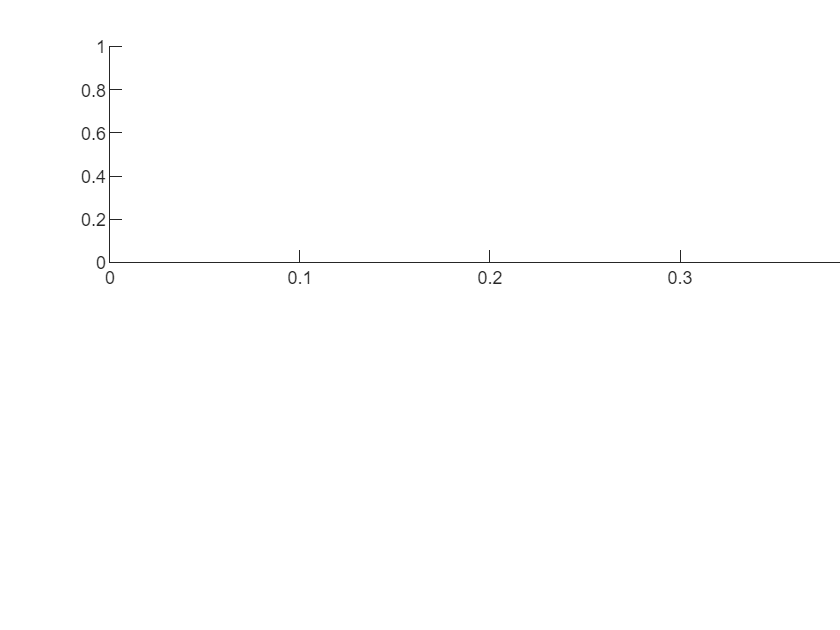

Error using gobjects
Size vector should be a row vector with integer elements.

Error in subplot>addAxesToGrid (line 634)
        grid = gobjects(nRows,nCols);

Error in subplot (line 568)
            addAxesToGrid(ax, nRows, nCols, row, col, position, plotId);

% plot configuration for given theta
% plot_configuration(theta_roots, N1, N2, D, x1, x2, y2, L2, L3, gamma)
for i=1:numel(theta_roots)
    i
    % subplot(numel(theta_roots), 1, i); % Adjust subplot layout as needed
    subplot(2, numel(theta_roots)/2, i); % Adjust subplot layout as needed

    plot_configuration(theta_roots(i), N1, N2, D, x1, x2, y2, L2, L3, gamma);

    axis equal
    title(["Theta = " + num2str(rad2deg(theta_roots(i))) + " Degrees"]); % Add title with the current theta value
    xlabel("X axis label");
    ylabel("Y axis label");
end

function figure = plot_configuration(theta, N1, N2, D, x1, x2, y2, L2, L3, gamma)
    %% coordinates based on theta
    x = N1(theta) / D(theta);
    y = N2(theta) / D(theta);
    x_p3 = x + L2 * (cos(theta + gamma)); % point connected to p3
    y_p3 = y + L2 * (sin(theta + gamma)); 
    x_p2 = x + L3*cos(theta); % point connected to p2
    y_p2 = y + L3*sin(theta);
    
    color = [rand,rand,rand];
    % lines
    figure = plot([0 x x_p3 x2],[0 y y_p3 y2], "Color",color);
    hold on
    plot([x x_p2 x1], [y y_p2 0], "Color", color);
    hold on
    plot([x_p3 x_p2], [y_p3 y_p2], "Color", color);
    hold on

    % points
    scatter([0 x x1 x2 x_p3 x_p2], [0 y 0 y2 y_p3 y_p2], "filled")
    % title("Theta = " + num2str(theta))
    hold off
end

% root finding funcitons
function root = inverse_quadratic_interpolation(func, x0, x1, x2, tol, max_iter)
    iter = 0;
    
    while iter < max_iter
        y0 = func(x0);
        y1 = func(x1);
        y2 = func(x2);

        term1 = (y1*y2)/((y0 - y1)*(y0 - y2)) * x0;
        term2 = (y0*y2)/((y1 - y0)* (y1 - y2)) * x1; % I think there is a typo in eq (6.9) in the book
        term3 = (y0*y1)/((y2 - y0)*(y2 - y1))*x2;
        xnew = term1 + term2 + term3;

        if abs(func(xnew)) < tol
            root = xnew;
            return;
        end

        x0 = x1;
        x1 = x2;
        x2 = xnew;
        
        iter = iter + 1;
    end
    
    warning('Maximum number of iterations reached without convergence.');
    root = xnew; 
end

function root = incremental_search(func, interval, delta_x)
    a = interval(1); 
    b = interval(2);
    x = a;
    root = [];
    
    while x <= b
        fx = func(x);
        
        if fx * func(x + delta_x) < 0
            root = [root, x];
        end
        % Move to next point
        x = x + delta_x;
    end
end

function root = false_position(func, interval, tol, max_iter)
    a = interval(1);
    b = interval(2);
    
    if func(a) * func(b) >= 0
        error('The function has the same sign at the endpoints of the interval. Unable to find a root.');
    end
    
    iter = 0;
    root = [];
    
    while iter < max_iter
        c = b - (func(b)*(a-b))/(func(a)-func(b));
        
        if abs(func(c)) < tol
            root = c;
            break;
        end
        
        if func(a) * func(c) < 0
            b = c;
        else
            a = c;
        end
        
        iter = iter + 1;
    end
    
    if iter == max_iter
        warning('Maximum number of iterations reached without convergence.');
    end
end

function root = bisection(func, interval, tol, max_iter)
    a = interval(1);
    b = interval(2);
    
    if func(a) * func(b) >= 0
        error('The function has the same sign at the endpoints of the interval. Unable to find a root.');
    end
    
    iter = 0;
    root = [];
    
    while iter < max_iter
        c = (a + b) / 2;
        
        if abs(func(c)) < tol
            root = [root, c];
        end
        
        if func(a) * func(c) < 0
            b = c;
        else
            a = c;
        end
        
        iter = iter + 1;
    end
    
    if iter == max_iter
        warning('Maximum number of iterations reached without convergence.');
    end
end

function root = modified_secant_method(func, x0, delta_x, tol, max_iter)
    iter = 0;
    root = []
    
    while iter < max_iter
        f0 = func(x0);
        f1 = func(x0 + delta_x * x0);
        
        if f1 - f0 == 0
            error('Division by zero. Unable to continue.');
        end
        
        x_next = x0 - f0 * delta_x * x0 / (f1 - f0);
        
        if abs(x_next - x0) < tol
            root = x_next;
            x_next = x_next + tol;
        end
        
        x0 = x_next;
        
        iter = iter + 1;
    end
    
    warning('Maximum number of iterations reached without convergence.');
    % root = x_next;
end


